# Grundlagen der Programmierung in MATLAB

Von Prof. Dr.-Ing. Jens Geisler, Stand 05.04.2021

## Tipp

- Beim Editieren von Code können sie mit der Tastenkombination Strg+R eine Zeile ganz schnell auskommentieren.

- Mit der Kombination Strg+T können Sie sie wieder einkommentieren.

## Bedingte Anweisungen

- Bedingte Anweisungen sind Teile eines Programmes, die nur ausgeführt werden, wenn eine bestimmte Bedingung erfüllt ist.

- Diese Bedingung muss ein Ausdruck sein, der als Ergebnis einen boolschen Wert hat. (Diese Ausdrücke haben sie bereits in den Grundlagen kennengelernt).

- Die einfachste und wichtigste Form einer Bedingten Anweisung ist die if-Anweisung. In ihr wird immer entweder der erste Zweig ausgeführt, wenn dei Bedingung wahr ist, oder der alternative Zweig.

- Der alternative Zweig kann wiederum durhc eine Bedingung in zwei Unterzweige aufgeteilt sein.

- Testen Sie den folgenden Code mit verschiedenen Werten für x.

x= 2;
if x>1
    fprintf('x ist größer als eins\n')
elseif x>2
    % Dieser Zweig kann nie erreicht werden!
    fprintf('x ist größer als zwei\n')    
elseif x>0
    fprintf('x ist größer als null\n')
else
    fprintf('x ist kleiner gleich null\n')
end

x ist größer als eins


- Im Zusammenhang mit Bedingten Anweisungen gibt es eine spezielle Variante der Und-Verküpfung, bei der nur der erste Term ausgewertet wird, wenn dieser schon falsch ist. Dies ist das **doppelte Kaufmanns-Und**: `&&`

- Ebenso wird beim **doppelten Strick** `||` nur der erste Term ausgewertet, wenn dieser schon wahr ist.

- Dies hat den Vorteil, dass Rechenzeit gespart werden kann:

clear s
if exist('s', 'var') && strcmpi(s, 'ja') % wenn die Variable s nicht existiert, wird der Zeichenkettenvergleich gar nicht erst ausgeführt
    fprintf('Sie haben Ja gewählt\n')
else
    fprintf('Sie haben Nein gewählt\n')
end

Sie haben Nein gewählt


## Schleifen

- Die einfachste und am häufigsten verwendete Scheife ist die `for`-Schleife.

- Bei der `for`-Schleife wird der Körper der Schleife so oft ausgeführt, wie ein Vektor Elemente hat.

- Dabei wird der Schleifenvariable in jedem Durchlauf der entsprechende Wert aus dem Vektor zugewiesen.

for i= 1:5
    fprintf('Hallo %d\n', i);
end

Hallo 1
Hallo 2
Hallo 3
Hallo 4
Hallo 5


- Dabei muss der Vektor nicht unbedingt in aufsteigender Reheinfolge sortiert sein.

X= [3.1 5.77 1.3];
for x= X
    fprintf('Hallo %f\n', x);
end

Hallo 3.100000
Hallo 5.770000
Hallo 1.300000


- Wenn in einer Schleife aus einem Vektor durch eine Berechnung durchgeführt werden soll, ist es oft sinnvoll, die Schleifenvarible über die Indizes des Vektors zählen zu lassen.

- Bei so einer Konstruktion sollte der Zielvektor vorab im Speicher mit Nullen vorbelegt werden, damit seine Größe in der Schleife nicht ständig neu angepasst werden muss.

X= [3.1 5.77 1.3];
Y= zeros(size(X));
for i= 1:length(X)
    Y(i)= X(i)^2+1;
end
[X; Y]

ans =     3.1000    5.7700    1.3000
   10.6100   34.2929    2.6900


- Beachten Sie aber, dass die meisten Berechnungen auch direkt mit Vektoren durchgeführt werden können und auch sollten, das Schleifen sehr viel langsamer sind.

X= linspace(0, 1, 1e6); % sehr viele Werte
Y= zeros(size(X));
tic                     % Stoppuhr starten
for i= 1:length(X)
    Y(i)= exp(X(i));
end
toc                     % Stoppuhr stoppen und anzeigen

Elapsed time is 0.049996 seconds.



tic
Y= exp(X);
toc

Elapsed time is 0.045784 seconds.


- Schleifen können auch frühzeitig abgebrochen werden:

Y= zeros(size(X));
for i= 1:length(X)
    Y(i)= exp(X(i));
    if Y(i)>(1+1e-5)
        break
    end
end
fprintf('Die Schleife wurde schon im %d-ten Durchlauf abgebrochen\n', i)

Die Schleife wurde schon im 11-ten Durchlauf abgebrochen


- Bei der Ausführung einer Schleife kann die Ausführung des Körpers ab einer bestimmten Stelle "kurzgeschlossen" werden:

for i= 1:10
    if mod(i, 2)==0
        continue
    end
    % Hier folgt typischer Weise eine lange Berechnung
    fprintf('Die Zahl %d ist ungerade\n', i)
end

Die Zahl 1 ist ungerade
Die Zahl 3 ist ungerade
Die Zahl 5 ist ungerade
Die Zahl 7 ist ungerade
Die Zahl 9 ist ungerade


- Eine weitere Form der Schleife, die nicht eine feste Anzahl von Durchläufen ausgeführt wird, sondern solange, wie eine Bedingung wahr ist, ist die `while`-Schleife:.

- Hier ist besondere Acht zu geben, dass die Bedingung irgendwann wirklich wahr wird, da man ansonsten eine Endlosschleife erhält.

- **Endlosschleifen oder sonst auch "hängende" Programme können Sie beenden, indem Sie in das Komanndo-Fenster klicken und dann Strg+C drücken.**

- Warum wird in der folgenden Schleife die Bedingung scheinbar nicht eingehalten?

x= [0 1];
while x(end)<50
    x(end+1)= x(end) + x(end-1);
end
% Die Fibonacci-Reihe bis x<50?
x

x =      0     1     1     2     3     5     8    13    21    34    55


## Skripte

- Skripte können einfache Programme oder Unterprogramme, Prozeduren bzw. Routinen sein, je nachdem, wie Sie sie verwenden oder aufrufen wollen.

- Die wichtigste Eigenschaft von Skripten ist, dass Sie ihre Variablen im Haupt-Workspace ablegen, so als ob Sie alle Zeilen des Skripts der Reihe nach an der Kommandozeile eingegeben hätten.

- Sie teilen sich daher auch alle Variablen mit allen anderen Skripten und Befehlen, die Sie zuvor im Workspace erzeugt haben.

- Ein neues leeres Skript erzeugen Sie mit dem New-Button oben links im Toolbar:

- 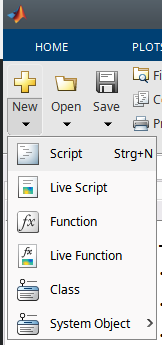

- Beim Speichern geben Sie der Datei einen Namen. Dieser Dateiname ist auch gleichzeitig der Name des Skripts. Der Name muss daher den gleichen Regeln folgen, wie der von Variablen.

- Erstellen Sie ein Skript mit Namen `Skript1`, in dem nur der Variablen x ein Wert zu gewiesen wird.

- An der Kommandozeile löschen Sie den Workspace. Rufen Sie dann das Skript auf und überprüfen Sie, den Inhalt der zugewiesenen Variablen.

- Schreiben Sie nun ein zweites Skript mit Namen `Skript2`, das die Berechnung y=x*2 durchführt und rufen Sie dieses Skript in `Skript1` einmal vor und einmal nach der Zuweisung von x auf.

- Weisen Sie an der Kkommandozeile x nun einen anderen Wert zu und rufen Sie nun wieder `Skript1` auf. welchen Wert hat y?

- Löschen Sie x an der Kommandozeile und rufen Sie `Skript1` erneut auf. Was passiert?

- Obwohl der Austausch von Variablen über den Workspace möglich ist, ist dies generell keine "saubere" Lösung und die Eigenschaft, dass Skripte ihre Variablen ohne weiteres Zutun im Workspace hinterlassen ist auch eher suboptimal. Im schlimmsten Fall löschen oder überscshreiben Skripte sogar Variablen, dieSie zuvor im Workspace angelegt hatten. Daher sollten Sie Skripte nur für kleine, eigenständige Aufgaben nutzen.

## Funktionen

- Funktionen sind sozusagen Skripte mit einem eignen Workspace. Bei jedem Start einer Funktionist dieser Workspace leer und nach dem Ende der Funktin wird er weider gelöscht.

- Man spricht hier auch vom sogenannten Scope. D.i. die Verfügbarkeit, Lebensdauer und Sichtbarkeit von Variablen.

- Um Funktionen dennoch Werte übergeben zu können, und berechnete Werte zurückzuerhalten, haben Funktionen klar definierte Ein- und Ausgabeargumente.

- Eine Funktion ist, genau wie ein Skript, eine Textdatei mit der Endung ".m" im Namen.

- Der einzige Unterschied zu Skripten besteht darin, dass in Funktionen vor allem anderen Code der Funktionskopf steht. Dieser Beginnt mit dem

- Schlüsselwort `function` optional gefolgt von

- dem einen Rückgabeargument bzw. der Liste der Rückgabeargumente in eckigen Klammern, gefolgt von einem Gleichheitszeichen "`=`", gefogt von

- dem Funktionsnamen, der mit dem Namen der Datei identisch sein muss (ohne das ".m"), optional gefolgt von

- dem einen Übergabeargument bzw. der Liste der Übergabeargumente, immer in runden Klammern.

- Die Rück- und Übergabeargumente sind wie Variablennamen.

- Die beim Aufruf einer Funktion übergebenen Werte stehen in der Funktion unter dem Namen, der an der entsprechenden Stelle im Funktionskopf definiert wurde, zur Verfügung. Tatsächlich wird der übergebenen Wert zu einer Variablen mit diesem Namen im Workspace der Funktion.

- Ebenso müssen Rückgabewerte vor dem Ende der Funktion als Varable von der Funktion angelegt worden sein.

- Schreiben Sie die oben stehende Funktion in eine Datei.

- Funktionen werden mit den Übergabeargumenten in Runden Klammern aufgerufen.

- Die Werte der Argumente können aus Variablen stammen, sie können direkt als Zahlen eingegeben werden, oder sogar aus komplizierten Rechnungen hervorgehen.

- **Achtung: die Namen von übergebene und zurückgegebenen Variablen können den gleichen Naen haben, sie müssen es aber nicht!**

x= 2;
[y1, y2]= BeispielFun(2*2, x) % schauen Sie sich die Definition dieser Funktion weiter unten in diesem Skript an

y1 = 8

y2 = 8

- Se müssen die Rückgabewerte einer Funktion nicht "annehmen".

- Wenn Sie allerdins das zweite Argument haben möchten, müssen Sie auch das erste "annehmen". Welches Arguement in welcher Variablen gespeichert wird, hängt ausschließlich von der Position in der Liste der Argumente ab! Die Namen haben keinen Einfluss.

o2= BeispielFun(2*2, x) % hier wird trotzdem der Werte, der in der Funktion o1 heißt zurückgegeben!

o2 = 8

- Wenn Sie keine Argumente "annehmen" wird ohne ein Semikolon hinter der Funktion immer der erste Wert angezeigt.

BeispielFun(2*2, x)

ans = 8

BeispielFun(2*2, x);

- Wenn die Funktion dies zulässt, müssen Sie nicht unbedingt alle Eingabeargumente übergeben.

- Damit wird in vielen MATLAB-internen Funktionen das konkrete Verhalten einer Funktion beeinflusst.

y= BeispielFun(2*2)

y = 8

- Wenn Sie Argumente, die zwingend erforderlich sind, nicht angeben, wird ein Fehler erzeugt.

try
    y= BeispielFun(); % Hier könnten Sie auch nur BeispielFun; schreiben
    % Die Variable y wird wegen es Fehlers nicht angelegt
catch e
    warning(e.message)
end

- Das Gleiche passiert, wenn Sie Ausgabeargumente "annehmen" wollen, die in der Funktion nicht erzeugt wurden.

try
    [y1, y2]= BeispielFun(12)
    % Die Variablen y1 und y2 werden nicht angelegt!
catch  e
    warning(e.message)
end

- In Funktionen können Sie die Bearbeitung der Befehle mit dem Schlüsselwort `return` direkt beenden und zur aufrufenden Funktion zurückspringen:

- Zur Kommunikation mit dem Nutzer der Funktion, z.B. um über nicht akzeptierte Übergabeargumente zu informieren, können Sie die `error` oder die `warning` Funktionen nutzen.

- Die `error` Funktion gibt eine rote Nachricht im Kommandofenster aus und beendet die Ausführung der Funktion komplett. Es erscheint direkt wieder der Kursor an der Kommandozeile. Wenn die Funktion von einer anderen Funktion aufgerufen wurde, wird auch die aufrufende Funktion beendet. (Es sei denn, die aufrufende Funktion fängt den Fehler mit `try catch end` auf).

- Der Die warning Funktion gibt nur eine Meldung im Kommandofenster aus, die Verarbeitung des Code geht aber weiter:

warning('Hier ist etwas nicht ganz so, wie es sein sollte "%s" wird ignoriert', 'bla bla')

## Debuggen

- Sie Skripte und Funktionen an beliebigen Stellen anhalten und Schritt für Schritt ausführen.

- Dazu setzen Sie "Break-Points", das sind rote Kreise am linkens Rand neben den Zeilennummern, durch einfaches Klicken.

- Wenn Sie die Funktion oder das Skript nun ausführen, sei es durch klicken der Run Knopfes, durch Aufruf an der Kommandozeile oder durch einen indirekten Aufruf durch eine anderen Funktion, bleibt die Ausführung **vor oder am Anfang** der markierten Zeile stehen.

- Nun können Sie die Ausführung Schritt für Schritt mit dem Step-Knopf oder bis zum nächsten Break-Point mit dem Continue-Knopf fortführen.

- Wenn in der aktuellen Zeile eine Funktionsaufruf stattfindet, können Sie mit "Step In" auch in diese Funktion hineinspringen.

- Mit "Step Out" können Sie aus einer Funktion heraus zurück in den aufrufenden Code springen.

- Wenn Sie eine Funktion im Debugger angehalten haben, können Sie den Workspace dieser Funktion inspizieren.

- Sie können aber auch im Editor mit der Maus über Variablennamen schweben und, wenn diese Variable schon existert, erscheint eine kurze Übersicht über den Ihnalt der Varablen.

- Das mächtigste Werkzeug ist jedoch die Kommandozeile im Debugging Modus. Hier können Sie Befehle oder sogar ganze Programme im Kontext des gerade gültigen Workspaces ausführen.

- Dies ist besonders interssant, wenn Sie problematische Zeilen einer Funktion ausprobieren möchten, da die Fehler bei der Ausführung in der Debugging-Kommandozeile auftreten nicht zur Beendung der Funktion führen. Sie können die Zeile also auch mehrfach oder in Variationen ausführen.

- Aber Achtung: aus der Debugging-Kommandozeile heraus aufgerufene Funktionen können wiederum selbst in einem Break-Point stehen bleiben!

- Funktionen, die gerade Debuggt werden, können nicht verändert werden. Sobald Sie "Speichern" drüchen, fragt MATLAB Sie, ob Sie die Ausführung anhalten möchten.

## Übung

- Schreibe sie eine Funktion `allroots`, die zu einer gegebenen (komplexen) Zahl alle n-ten Wurzeln berechnet.

- Die Funktion soll als erstes Eingabeargument "z" die skalare Zahl, deren Wurzeln berechnet werde sollen, annehmen.

-  Als zweites optionales Argument "n" wird die skalare ganze Zahl > 0 übergeben, die die Wurzel angibt, die berechnet werden soll. Wenn das zweite Argument fehlt soll standardmäßig die Quardatwurzel berechnet werden.

- Das einzige Ausgabeargument "r" ist ein Vektor, der die n n-ten Wurzeln von z enthält.

- Machen Sie bei der Entwicklung Gebrauch vom Debugger!

- Die Wurzeln können nach der Gleichung $r=\left|z{\left|\right.}^{\frac{1}{n}} \cdot e^{i\cdot \left(\frac{\phi }{n}+k\cdot \frac{2\pi }{n}\right)} \right.$ berechnet werden. Dabei ist $\phi \;$ der Winkel der komplexen Zahl z, der mit der MATLAB Funktion `angle` berechnet werden kann und k ist eine Zahl, die die Werte 0 bis n-1 annimmt (probieren Sie aus, mit k als Vektor `0:(n-1)` zu rechnen).

- Schreiben Sie die Funktion so, dass die Anforderunge an die Übergabeargumente geprüft und entsprechende Meldungen (error und/oder warning) ausgegeben werden.

- Schreiben Sie eine Funktion zum Testen von `allroots`, die die gleichen Argumente wie annimmt, damit `allroots` aufruft und dann den Realteil und den Imaginärteil des Ergebnisses (die n Wurzeln) in einem Karthesischen Koordinatensystem als rote Kreuze plottet.

- Als weiteren Test könnten Sie die n Wurzeln aufsummieren. Diese Summe ist idealerweise gleich null. Praktisch sollte sie einen sehr kleinen Wert haben (z.B. `abs(sum(r))<3*eps`).

## Sonstiges

- MATLAB kann auch als Objekt-Orientierte Programmiersprache verwendet werden. Dies soll hier jedoch nicht weiter besprochen werden.

- Sie werden jedoch an vielen Stellen damit konfrontiert, wenn Sie mit MATLAB internen Objekten bzw. Klassen interagieren.

- Objekte sind in vieler Hinsicht wie Struktur-Variablen, nur das sie neben den Daten-Feldern auch Felder haben, die eine Funktion sind.

- Diese Funktionen in Objekten heißen Member-Funktionen und werden mit der Punkt-Notation aufgerufen:

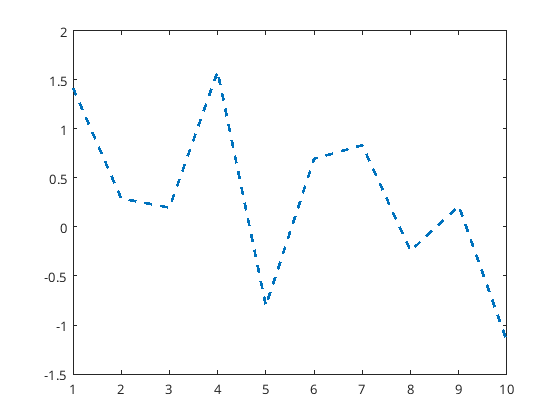

ax= plot(1:10, randn(10, 1));
ax.set('LineWidth', 2) % Einfaches Beispiel einer Member-Funktion
% Die set-Member-Funktion erlaubt den Zugriff auf die Properties des
% Linien-Objekts. Diese können alternativ auch direkt als Felder angesprochen
% werden:
ax.LineStyle= '--';

- Die class Funktion hilft Ihnen beim Umgang mit Variablen herauszufindne, zu welcher Klasse ein Objekt gehört:

class(ax)

ans = 'matlab.graphics.chart.primitive.Line'

x= 13;
class(x)

ans = 'double'

## Anhang

Hier wird eine Funktion deklariert, die weiter oben verwendet wird. Dies ist nötig, da Funktionen in Live-Skripten nur am Ende stehen dürfen.

function [o1, o2]= BeispielFun(i1, i2)
    if exist('i2', 'var')
        o2= i1*i2;
    end
    o1= 2*i1;
end